# Sessió 6

## Xavier Martín Ballesteros i Adrià Cabeza Sant'Anna

### Implementar una dilatació 

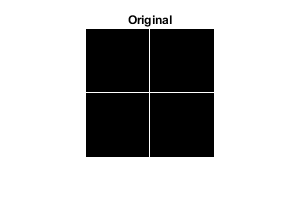

im = false(128);
im(64,:)=1;
im(:,64)=1;
imshow(im), title('Original')

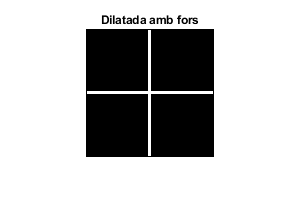

imblanc = im(im==255);
image = zeros(size(im));
EE = [ 0 1 0; 1 1 1; 0 1 0];
[rows cols] = size(im);

% amb fors
for i = 2:rows-1
    for j = 2: cols -1 
        image(i,j) = max(max(im(i-1:i+1,j-1:j+1) & EE));
    end
end
figure, imshow(image), title('Dilatada amb fors')

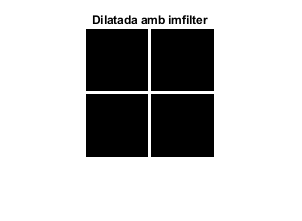

% amb imfilter
image2 = imfilter(im, EE);
figure, imshow(image2), title('Dilatada amb imfilter')

### Dilatació i erosió

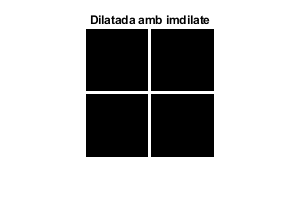

% implementat
ee = strel('disk',1); 
dil = imdilate(im,ee);
figure, imshow(dil), title('Dilatada amb imdilate')

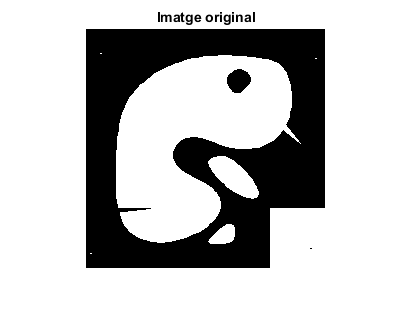

ee = strel('disk',5);
im = imread('blob.tif');
imshow(im), title('Imatge original');

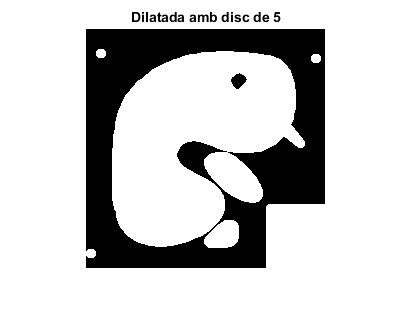

dil = imdilate(im,ee);
ero = imerode(im,ee);
figure, imshow(dil), title('Dilatada amb disc de 5')

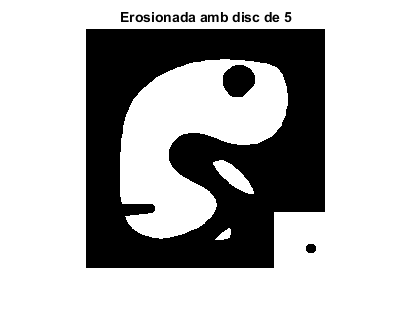

figure, imshow(ero), title('Erosionada amb disc de 5')

### Operacions composades

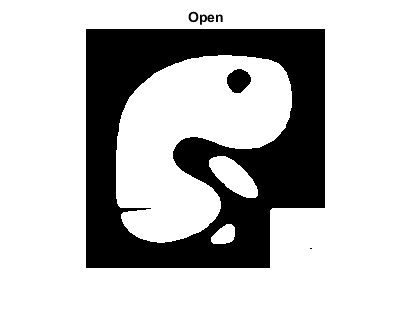

op = imdilate(ero, ee);
figure, imshow(op), title('Open')

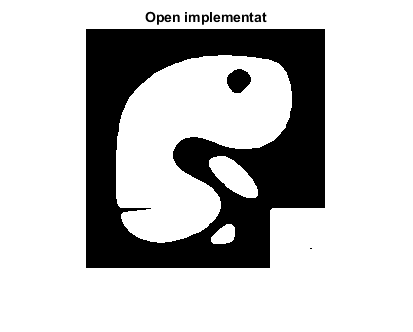

op2 = imopen(im,ee);
figure, imshow(op2), title('Open implementat')

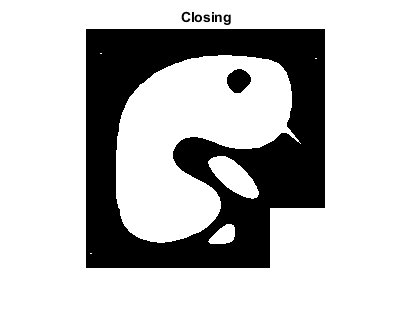

cl = imerode(dil, ee);
figure, imshow(cl), title('Closing')

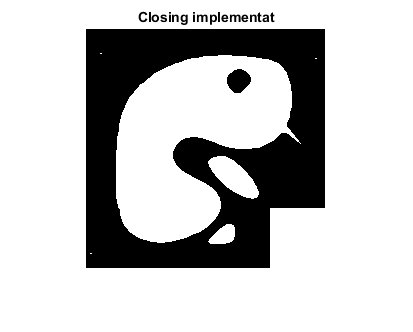

cl2 = imclose(im,ee);
figure, imshow(cl2), title('Closing implementat')

### Laplacià i conill

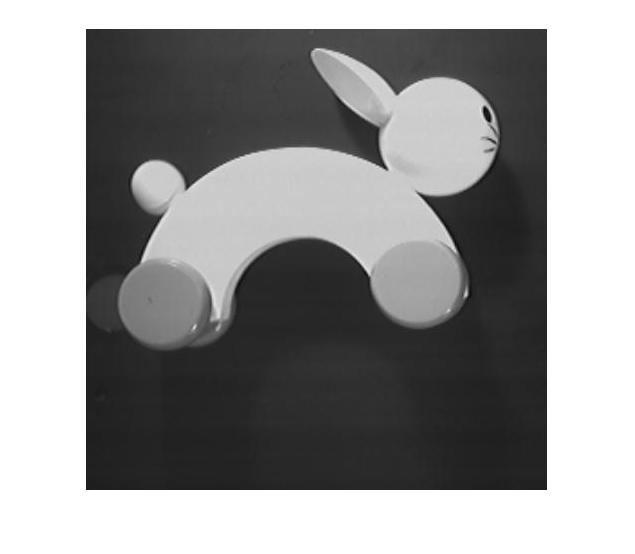

im = imread('rabbit.jpg');
imshow(im);

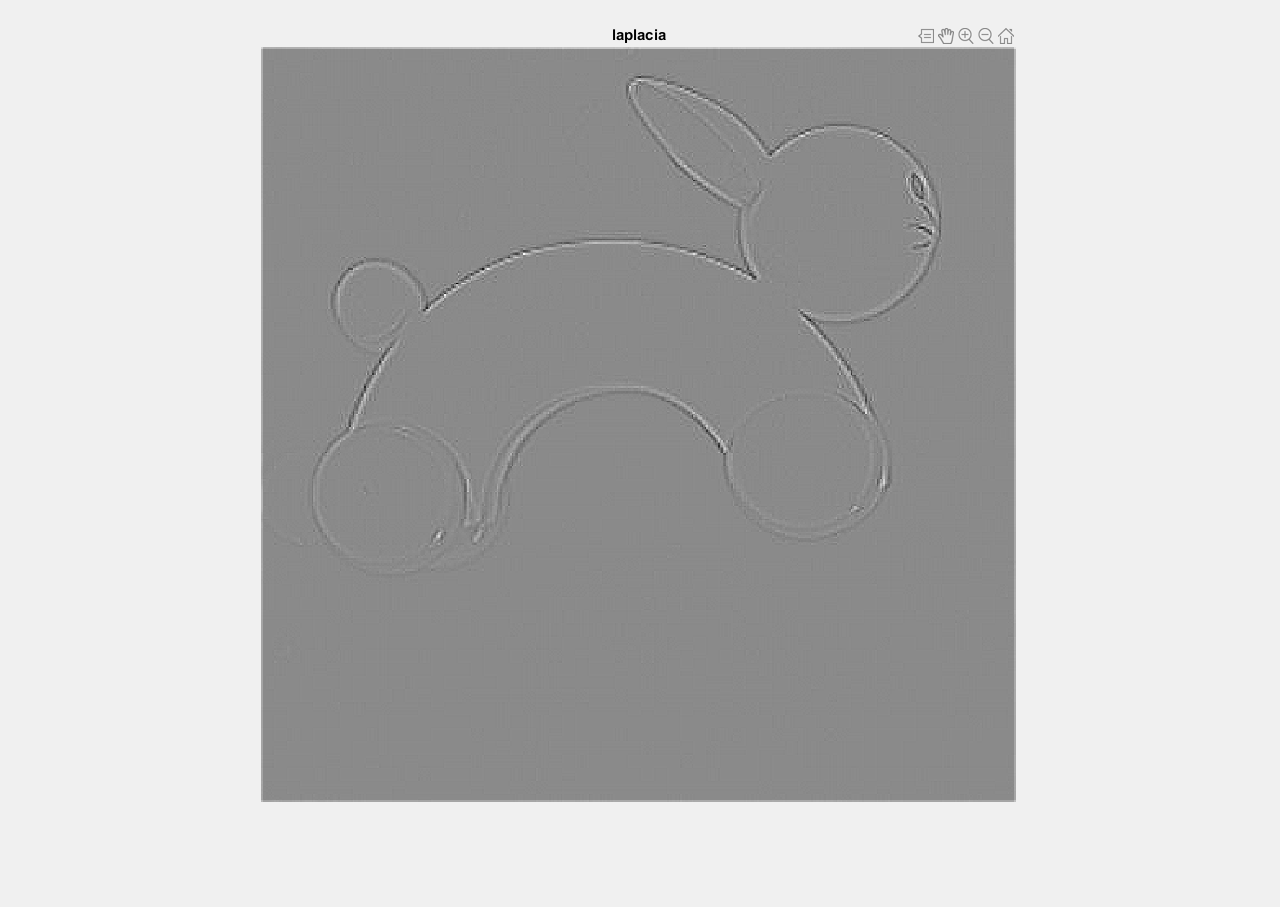

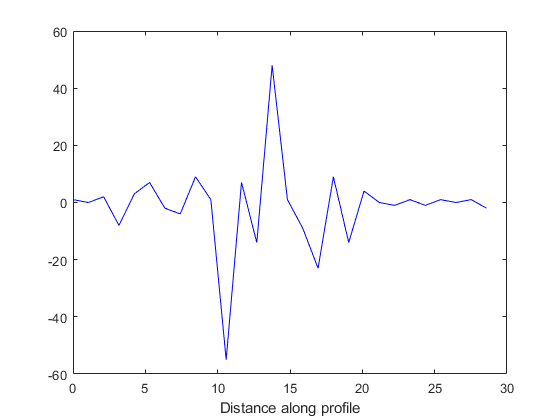

w = [0 -1 0 ; -1  4 -1; 0 -1 0];
lap = imfilter(double(im), w);
figure, imshow(lap,[]), title('laplacia');
improfile

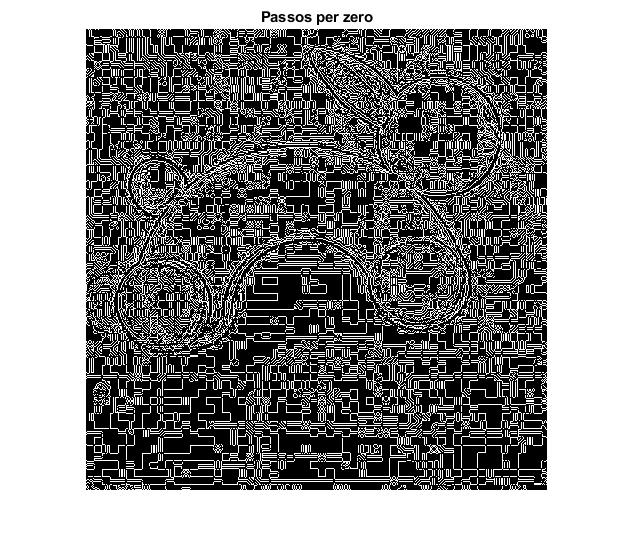

neg=lap<0;
pos=lap>0;
ee = strel('disk',1);
negdil = imdilate(neg,ee);
ppz = negdil&pos;
figure, imshow(ppz),title('Passos per zero')

### Residus

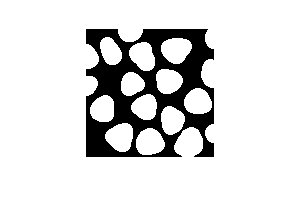

im = imread('blob3.tif');
imshow(im)

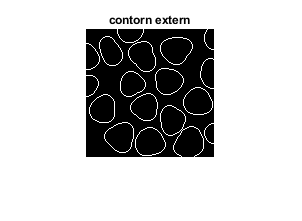

dil = imdilate(im,ee);
ce = imsubtract(dil,im);
figure, imshow(ce), title('contorn extern');

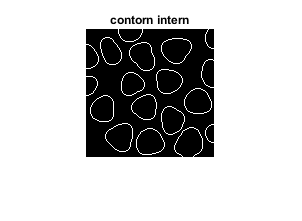

ero = imerode(im,ee);
ci = imsubtract(im,ero);
figure, imshow(ci), title('contorn intern');

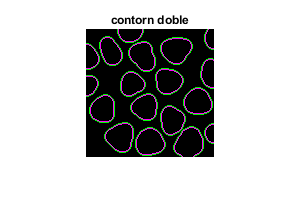

cd = imfuse(ce,ci);
figure, imshow(cd), title('contorn doble');

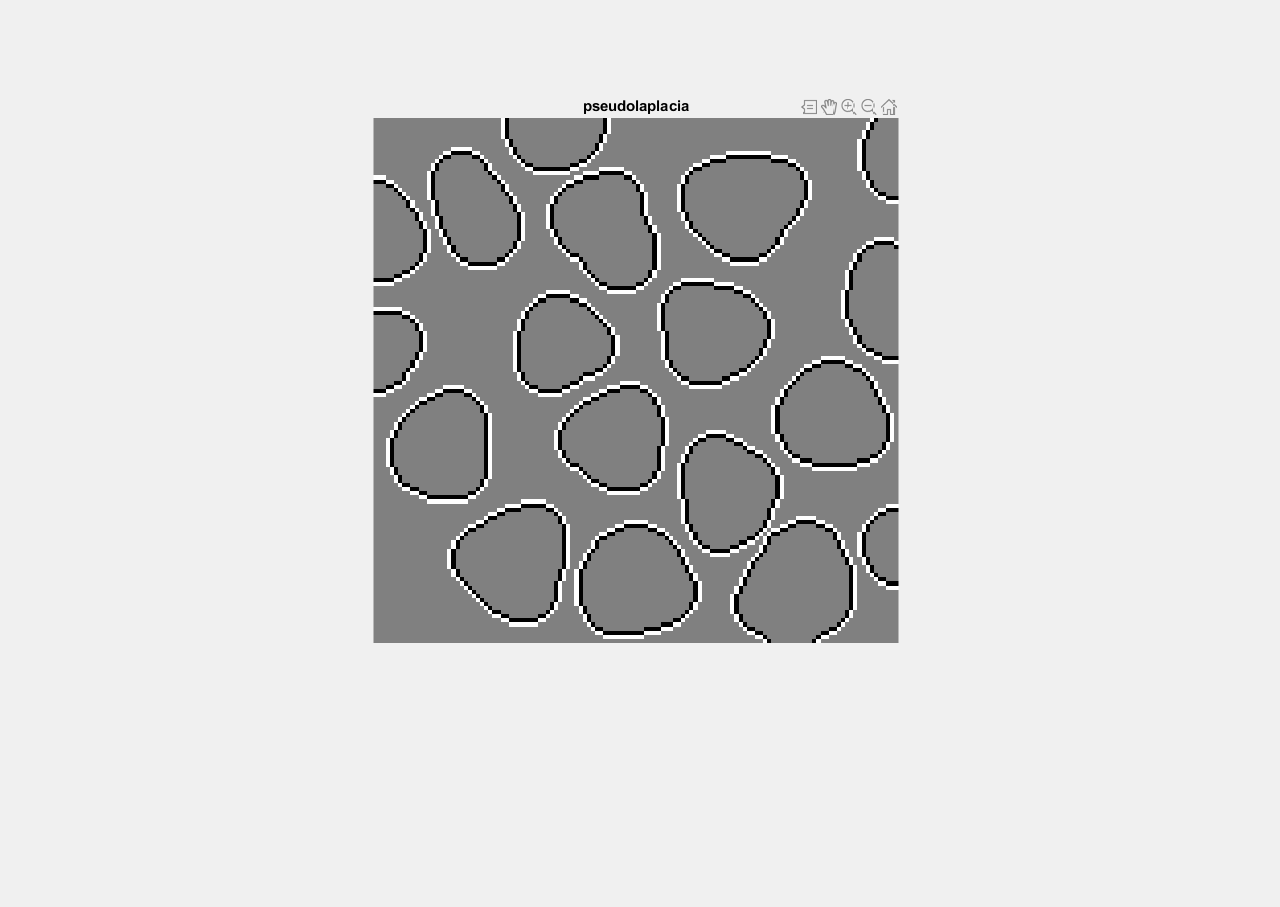

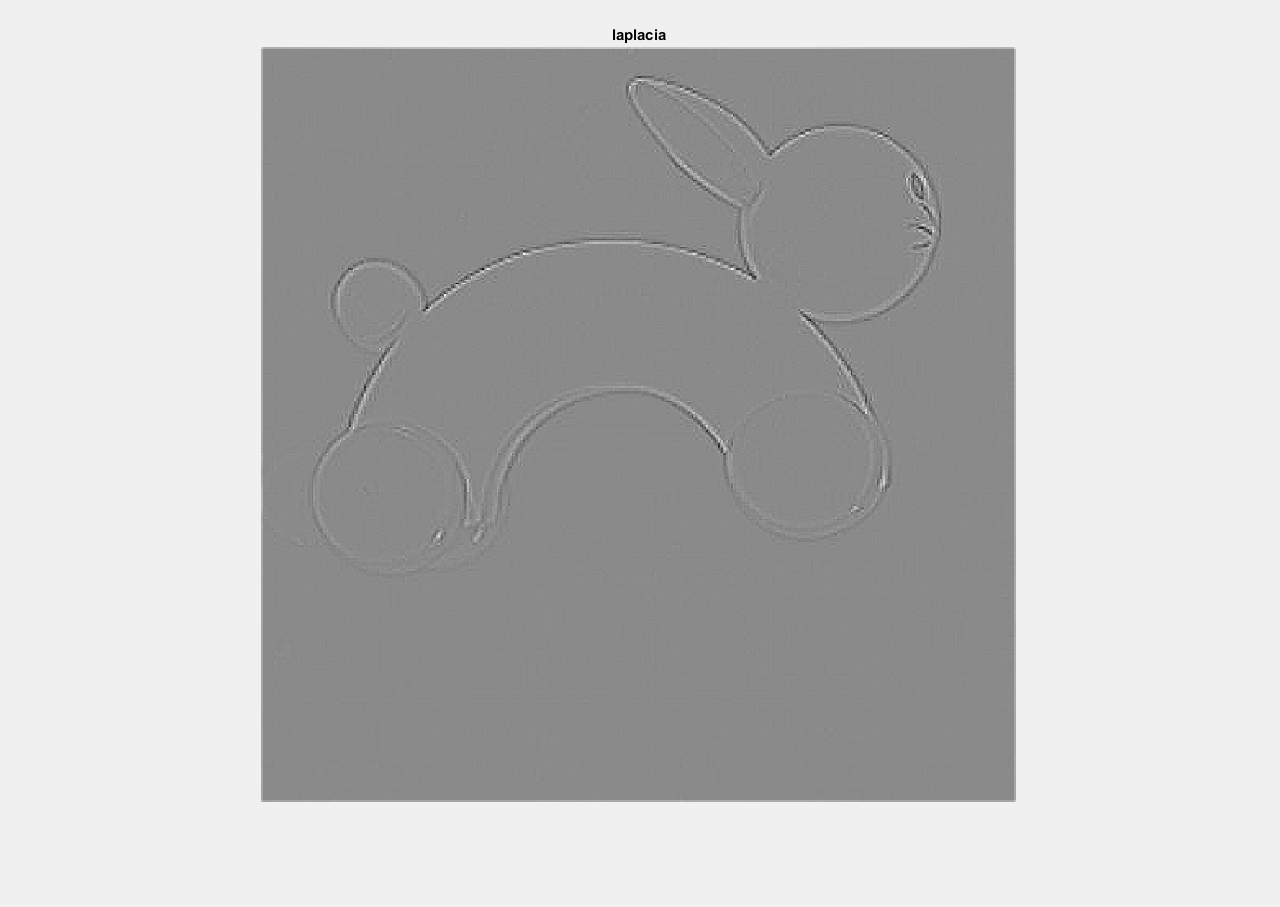

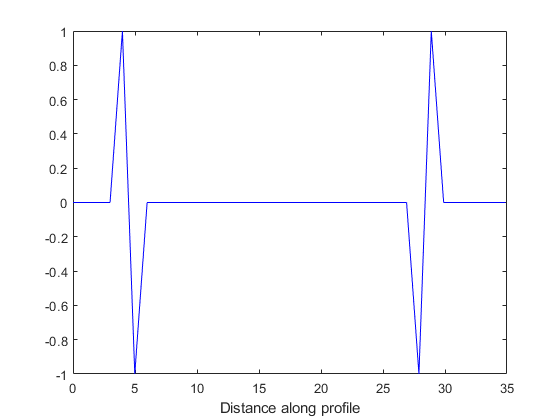

lap = imsubtract(double(ce),double(ci));
figure, imshow(lap,[]), title('pseudolaplacia');
improfile

### Dilatació condicional

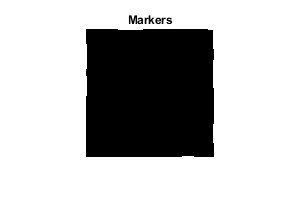

mark = im;
mark(2:end-1,2:end-1)=0;
figure, imshow(mark), title('Markers');

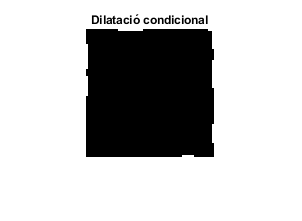

dil = imdilate(mark,ee);
dilc = dil&im;
figure, imshow(dilc), title('Dilatació condicional');

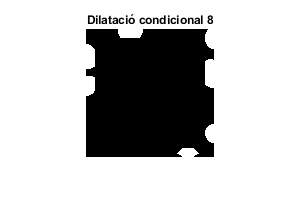

dilc= imdilate(dilc,ee)&im;
dilc= imdilate(dilc,ee)&im;
dilc= imdilate(dilc,ee)&im;
dilc= imdilate(dilc,ee)&im;
dilc= imdilate(dilc,ee)&im;
dilc= imdilate(dilc,ee)&im;
dilc= imdilate(dilc,ee)&im;
figure, imshow(dilc), title('Dilatació condicional 8');

### Reconstrucció

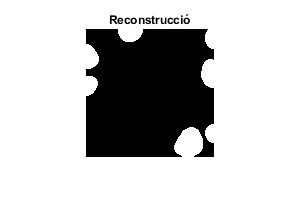

rec = imreconstruct(mark,im);
figure, imshow(rec), title('Reconstrucció')

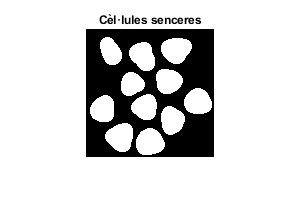

res = imsubtract(im, rec);
figure, imshow(res), title('Cèl·lules senceres')

### Exercici

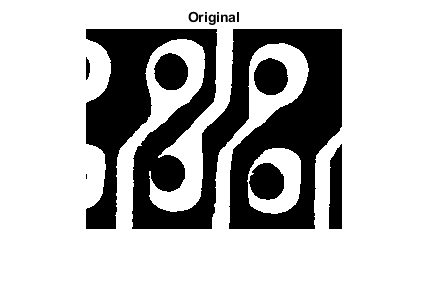

close all 
im= imread('pcbholes.tif');
imshow(im),title('Original');

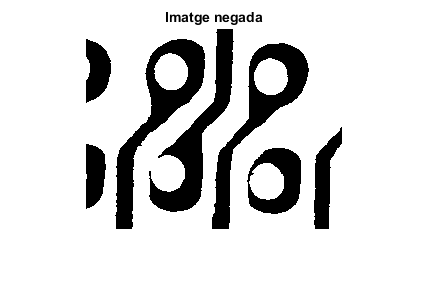

Nim =~ im;
figure, imshow(Nim), title('Imatge negada');

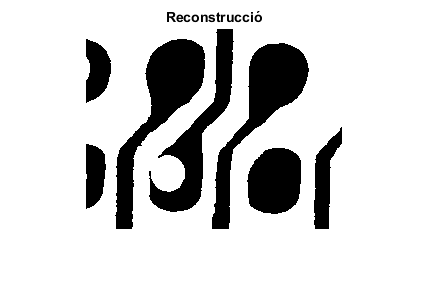

mark = Nim;
mark(2:end-1,2:end-1)=0;
rec = imreconstruct(mark,Nim);
figure, imshow(rec), title('Reconstrucció')

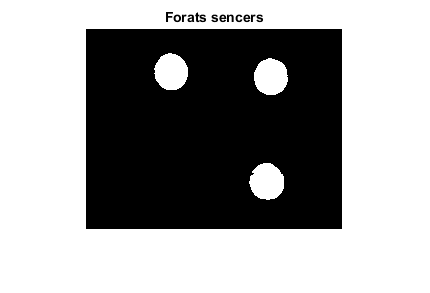

res = imsubtract(Nim,rec);
% res = bwlabel(res);
figure, imshow(res), title('Forats sencers')

### Cerca de marques

clear all 
close all
im = imread('tools.tif');
imshow(im), title('Original')
ee = strel('disk',7);
mark = imerode(im,ee);
figure,imshow(mark),title('Markers')
rec = imreconstruct(mark,im);
figure, imshow(rec), title('Reconstrucció')
close all 

### Exercici final

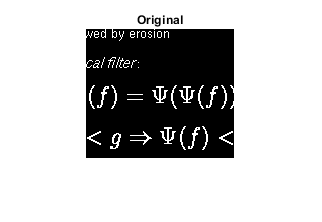

im = imread('letters.tif');
imshow(im), title('Original');

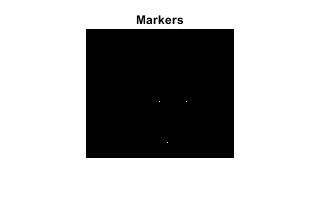

ee = [0 0 0 1 1 0 0 0;
      0 0 0 1 1 0 0 0;
      1 1 1 1 1 1 1 1];
mark = imerode(im,ee);
figure,imshow(mark),title('Markers')

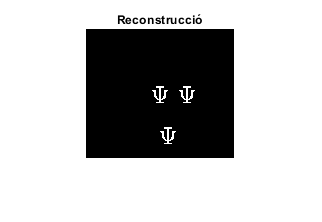

rec = imreconstruct(mark,im);
figure, imshow(rec), title('Reconstrucció')